Firstly, let's set the parameters for our project, based on the .pdf file in Canvas.

% Simulation time
t0 = 0;              % start time [days]
tf = 59;             % end time [days]
dt = 0.1;            % time resolution [days]
tspan = t0:dt:tf;    % time vector

% Initial Conditions (define separately for clarity)
T0 = 49.0497;   % Initial tumor volume [mm^3]
C0 = 0.0171;     % Initial chemo drug concentration [mg/ml] original value 0.171

%% Tumor and Drug Parameters
C_M   = 1e4;           % Carrying capacity of tumor cells [mm^3]
d_c   = 0.1030;        % Natural death rate of tumor cells [/day]
b     = 0.1685;        % Death rate due to chemotherapy [/day]
lambda_ce = 0.4579;    % Tumor cell proliferation rate [/day]
d_d   = 0.1825;        % Clearance rate of chemotherapy drug [/day]
b_k   = 1.0839e-6;     % Drug clearance due to binding [mg/ml.day.mm^3]

%% Endothelial (Vascular) Parameters
E_thres = 4.5;         % Hypoxia threshold [mm^3]
lambda_e = 0.03;       % Endothelial proliferation rate [/day]
E_M   = 10;            % Carrying capacity of endothelial cells [mm^3]
d_e   = 0.05;          % Endothelial cell death rate [/day]

%% VEGF and Anti-VEGF Parameters
d_v   = 0.1;           % Natural decay rate of VEGF [/day]
d_b   = 0.05;          % Clearance rate of anti-VEGF drug [/day]
lambda_v0 = 1e-3;      % Baseline VEGF secretion rate [mg/ml.day.mm^3]
k     = 5;             % VEGF-induced endothelial proliferation [/day]
mu_B  = 10;            % VEGF removal when binding anti-VEGF [ml/day.mg]
mu_Bk = 0.15;          % Anti-VEGF clearance via binding [ml/day.mg]

%% Therapy Dosing Ranges (for future design or sensitivity analysis)
dose_chemo   = 0.0171;   % Chemotherapy dose [mg/ml], range is [0.002, 0.05]
dose_antiVEGF = 0.02;  % Anti-VEGF dose [mg/ml], range is [0.003, 0.07] 

% Initial value of variables likes VEGF, endothelial cells, etc.
E0 = 1.75;      % Initial endothelial density [mm^3] (within the 0.5–3 range)
V0 = 1;       % Initial VEGF [mg/ml] (within 0.5-1.5 range)
A0 = 0.02;      % Initial anti-VEGF drug concentration [mg/ml]

%% Matrix of coefficients with patients. Each row is a parameter, each column is a patient (by number in the .docx file)
% Order of rows:
% 1. Proliferation rate of the tumor cells
% 2. Carrying capacity tumor cells
% 3. Baseline VEGF secretion by tumor cells
% 4. Clearance of drugs by the kidneys


patients_coeffs = [
    1.20, 0.85, 1.50, 0.70, 1.05;  % Proliferation rate
    0.90, 0.80, 1.35, 1.05, 1.10;  % Carrying capacity
    1.50, 1.20, 0.90, 1.10, 0.80;  % VEGF secretion
    0.70, 1.10, 1.50, 0.85, 1.20   % Drug clearance
];

The Growth **model declaration **and** initial **results, with only **initial drugs dosing**.

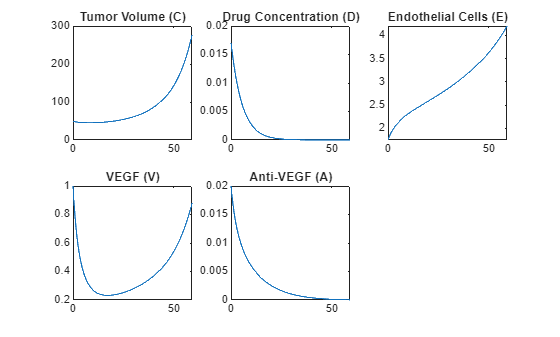

x0_extended = [T0; C0; E0; V0; A0];

params_extended = struct( ...
    'd_c', d_c, ...
    'b', b, ...
    'lambda_ce', lambda_ce, ...
    'd_d', d_d, ...
    'b_k', b_k, ...
    'c_M', C_M, ...
    'lambda_e', lambda_e, ...
    'd_e', d_e, ...
    'E_thres', E_thres, ...
    'E_M', E_M, ...
    'd_v', d_v, ...
    'lambda_v0', lambda_v0, ...
    'd_b', d_b, ...
    'k', k, ...
    'mu_B', mu_B, ...
    'mu_Bk', mu_Bk ...
);

% Run simulation
[T1, Y1] = ode15s(@(t,y) Model_extended(t,y,params_extended), tspan, x0_extended);

% Plotting the variables of the extendedn model

figure;
subplot(2,3,1); plot(T1, Y1(:,1)); title('Tumor Volume (C)');
subplot(2,3,2); plot(T1, Y1(:,2)); title('Drug Concentration (D)');
subplot(2,3,3); plot(T1, Y1(:,3)); title('Endothelial Cells (E)');
subplot(2,3,4); plot(T1, Y1(:,4)); title('VEGF (V)');
subplot(2,3,5); plot(T1, Y1(:,5)); title('Anti-VEGF (A)');

The comparison between **no VEGF** and **yes VEGF/anti-VEGF drug**.

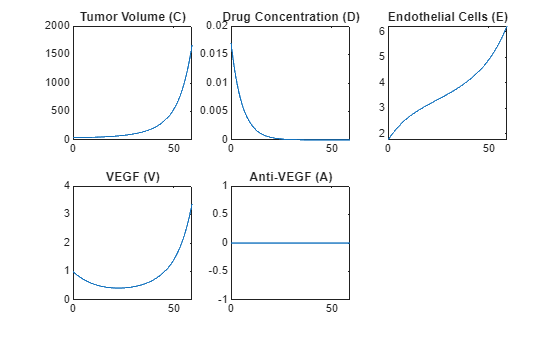

% Initial conditions (A0 = 0)
x0_no_anti_vegf = [T0; C0; E0; V0; 0];

% Run simulation using original Model_logistic (no VEGF, no E, no A)
[T2, Y2] = ode15s(@(t, y) Model_extended(t, y, params_extended), tspan, x0_no_anti_vegf);

% Plotting the variables of the extendedn model without anti-VEGF

figure;
subplot(2,3,1); plot(T2, Y2(:,1)); title('Tumor Volume (C)');
subplot(2,3,2); plot(T2, Y2(:,2)); title('Drug Concentration (D)');
subplot(2,3,3); plot(T2, Y2(:,3)); title('Endothelial Cells (E)');
subplot(2,3,4); plot(T2, Y2(:,4)); title('VEGF (V)');
subplot(2,3,5); plot(T2, Y2(:,5)); title('Anti-VEGF (A)');

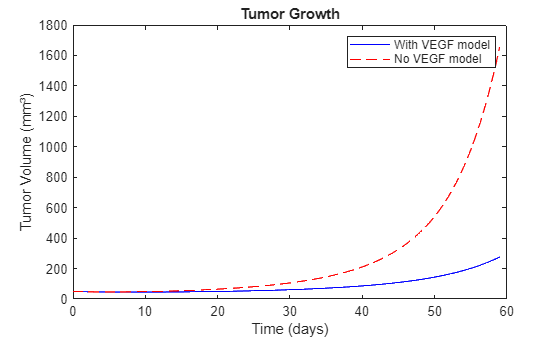


% Plotting Tumor volume (C) for difference between models

figure;
plot(T1, Y1(:,1), 'b-', T2, Y2(:,1), 'r--');
xlabel('Time (days)');
ylabel('Tumor Volume (mm³)');
title('Tumor Growth');
legend('With VEGF model', 'No VEGF model');

The models playing with **continuous drugs dosing for both **(Work in progress).

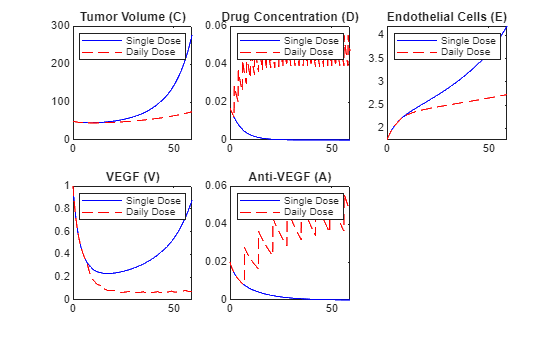

x0_everyday_injection = [T0; C0; E0; V0; A0];

% Computing the ODEs for the 1st day

[T3, Y3] = ode15s(@(t, y) Model_extended(t, y, params_extended), [0:dt:1], x0_everyday_injection); %[0:dt:1] means simulating day 1, with numbers every 0.1 day (or differently defined dt)

% Computing the ODEs for the subsequent days

for i = 1:1:tf-1
    C_end = Y3(end,1);
    D_end = Y3(end,2) + (mod(i,2)==0) * dose_chemo; % inject chemotherapy bidaily
    E_end = Y3(end,3);
    V_end = Y3(end,4);
    A_end = Y3(end,5) + (mod(i,7)==0) * dose_antiVEGF; % inject anti-VEGF every week
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T3(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T3 = [T3; Tstep(2:end)];
    Y3 = [Y3; Ystep(2:end, :)];
end

figure;

subplot(2,3,1);
plot(T1, Y1(:,1), 'b-', T3, Y3(:,1), 'r--');
title('Tumor Volume (C)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,2);
plot(T1, Y1(:,2), 'b-', T3, Y3(:,2), 'r--');
title('Drug Concentration (D)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,3);
plot(T1, Y1(:,3), 'b-', T3, Y3(:,3), 'r--');
title('Endothelial Cells (E)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,4);
plot(T1, Y1(:,4), 'b-', T3, Y3(:,4), 'r--');
title('VEGF (V)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,5);
plot(T1, Y1(:,5), 'b-', T3, Y3(:,5), 'r--');
title('Anti-VEGF (A)');
legend('Single Dose', 'Daily Dose');

The models playing with **continuous drugs dosing only for Anti-VEGF**.

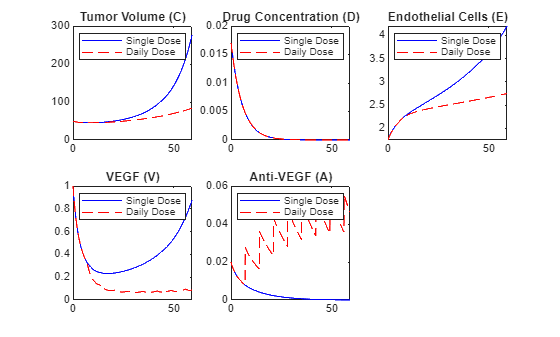

x0_everyday_injection = [T0; C0; E0; V0; A0];

% Computing the ODEs for the 1st day

[T4, Y4] = ode15s(@(t, y) Model_extended(t, y, params_extended), [0:dt:1], x0_everyday_injection); %[0:0.1:1] means simulating day 1, with numbers every 0.1 day (or differently defined dt)

% Computing the ODEs for the subsequent days

for i = 1:1:tf-1
    C_end = Y4(end,1);
    D_end = Y4(end,2);
    E_end = Y4(end,3);
    V_end = Y4(end,4);
    A_end = Y4(end,5) + (mod(i,7)==0) * dose_antiVEGF; % inject anti-VEGF every week
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T4(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T4 = [T4; Tstep(2:end)];
    Y4 = [Y4; Ystep(2:end, :)];
end

figure;

subplot(2,3,1);
plot(T1, Y1(:,1), 'b-', T4, Y4(:,1), 'r--');
title('Tumor Volume (C)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,2);
plot(T1, Y1(:,2), 'b-', T4, Y4(:,2), 'r--');
title('Drug Concentration (D)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,3);
plot(T1, Y1(:,3), 'b-', T4, Y4(:,3), 'r--');
title('Endothelial Cells (E)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,4);
plot(T1, Y1(:,4), 'b-', T4, Y4(:,4), 'r--');
title('VEGF (V)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,5);
plot(T1, Y1(:,5), 'b-', T4, Y4(:,5), 'r--');
title('Anti-VEGF (A)');
legend('Single Dose', 'Daily Dose');

The models playing with **continuous drugs dosing only for the Chemotherapeutic**.

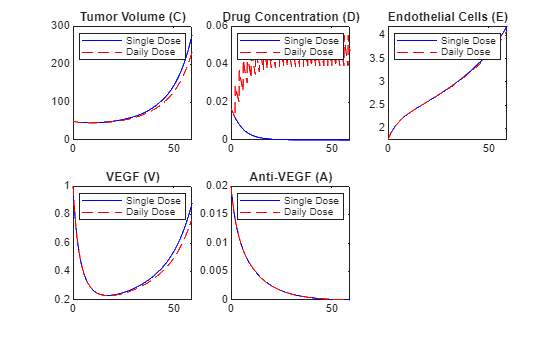

x0_everyday_injection = [T0; C0; E0; V0; A0];

% Computing the ODEs for the 1st day

[T5, Y5] = ode15s(@(t, y) Model_extended(t, y, params_extended), [0:dt:1], x0_everyday_injection); %[0:0.1:1] means simulating day 1, with numbers every 0.1 day (or differently defined dt)

% Computing the ODEs for the subsequent days

for i = 1:1:tf-1
    C_end = Y5(end,1);
    D_end = Y5(end,2) + (mod(i,2)==0) * dose_chemo; % inject chemotherapy bidaily
    E_end = Y5(end,3);
    V_end = Y5(end,4);
    A_end = Y5(end,5);  
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T5(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T5 = [T5; Tstep(2:end)];
    Y5 = [Y5; Ystep(2:end, :)];
end

figure;

subplot(2,3,1);
plot(T1, Y1(:,1), 'b-', T5, Y5(:,1), 'r--');
title('Tumor Volume (C)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,2);
plot(T1, Y1(:,2), 'b-', T5, Y5(:,2), 'r--');
title('Drug Concentration (D)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,3);
plot(T1, Y1(:,3), 'b-', T5, Y5(:,3), 'r--');
title('Endothelial Cells (E)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,4);
plot(T1, Y1(:,4), 'b-', T5, Y5(:,4), 'r--');
title('VEGF (V)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,5);
plot(T1, Y1(:,5), 'b-', T5, Y5(:,5), 'r--');
title('Anti-VEGF (A)');
legend('Single Dose', 'Daily Dose');

**Comparing** all models

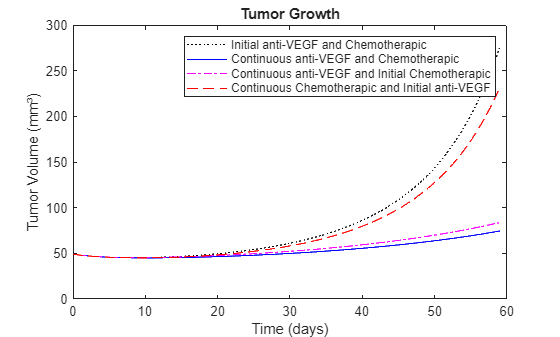


figure;
plot(T1, Y1(:,1), 'k:', ...                                    % Both parameters initial only
     T3, Y3(:,1), 'b-', ...                                    % Continuous VEGF and Chemotherapic model
     T4, Y4(:,1), 'm-.', ...                                   % Continuous VEGF and Initial Chemotherapic model
     T5, Y5(:,1), 'r--');                                      % Continuous Chemotherapic, Initial VEGF model
xlabel('Time (days)');
ylabel('Tumor Volume (mm³)');
title('Tumor Growth');
legend('Initial anti-VEGF and Chemotherapic', ...
       'Continuous anti-VEGF and Chemotherapic', ...
       'Continuous anti-VEGF and Initial Chemotherapic', ...
       'Continuous Chemotherapic and Initial anti-VEGF');

The function needed to configure the model and calculate the tumour.

Changing the parameters based on patient's charateristics

% Number of patients
num_patients = size(patients_coeffs, 1);

% Preallocate results 
results_T = cell(num_patients, 1);  % stores time points per patient
results_Y = cell(num_patients, 1);  % stores solution matrix per patient


disp(num_patients);

     4



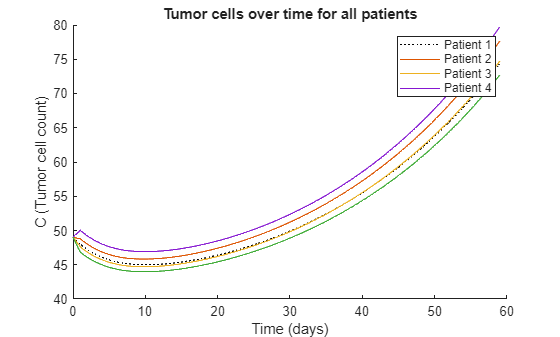


%% Running the loop for the patients, with nested loop for the ODEs solving
for i = 1:num_patients
    [T, Y] = ode15s(@(t, y) Model_extended_modifiable_params(t, y, params_extended, patients_coeffs(i, :)), [0:dt:1], x0_everyday_injection); %[0:0.1:1] means simulating day 1, with numbers every 0.1 day (or differently defined dt)
    for j = 1:1:tf-1
    C_end = Y(end,1);
    D_end = Y(end,2) + (mod(j,2)==0) * dose_chemo; % inject chemotherapy bidaily
    E_end = Y(end,3);
    V_end = Y(end,4);
    A_end = Y(end,5) + (mod(j,7)==0) * dose_antiVEGF; % inject anti-VEGF every week
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T = [T; Tstep(2:end)];
    Y = [Y; Ystep(2:end, :)];
    end
    results_T{i} = T;
    results_Y{i} = Y;
end

figure; hold on;  % Create figure and allow multiple plots
plot(T3, Y3(:,1), 'k:');
for k = 1:num_patients
    plot(results_T{k}, results_Y{k}(:, 1));  % Column 1 = variable C
end
title('Tumor cells over time for all patients');
xlabel('Time (days)');
ylabel('C (Tumor cell count)');
legend(arrayfun(@(x) sprintf('Patient %d', x), 1:num_patients, 'UniformOutput', false));
hold off;  

The Sensitivity analysis script

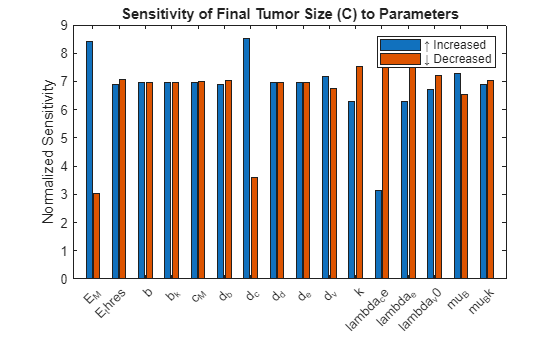

sensitivities = Sensitivity_analysis(Y1, params_extended, x0_extended, tspan, 0.1, [0, 2], [dose_antiVEGF, 7], tf, dt); % Best to keep the doses of anti-VEGF to 0

Making a comparison graph for the sensitive variables values

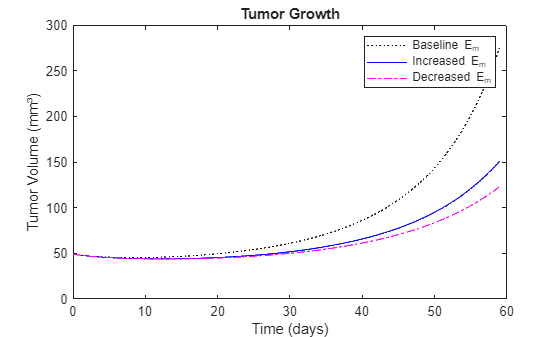


%% Using non-dosing model as that captures the parameters sensitivity better

params_extended_increased_Em = struct( ...
    'd_c', d_c, ...
    'b', b, ...
    'lambda_ce', lambda_ce, ...
    'd_d', d_d, ...
    'b_k', b_k, ...
    'c_M', C_M, ...
    'lambda_e', lambda_e, ...
    'd_e', d_e, ...
    'E_thres', E_thres * 1.2, ...
    'E_M', E_M, ...
    'd_v', d_v, ...
    'lambda_v0', lambda_v0, ...
    'd_b', d_b, ...
    'k', k, ...
    'mu_B', mu_B, ...
    'mu_Bk', mu_Bk ...
);

params_extended_decreased_Em = struct( ...
    'd_c', d_c, ...
    'b', b, ...
    'lambda_ce', lambda_ce, ...
    'd_d', d_d, ...
    'b_k', b_k, ...
    'c_M', C_M, ...
    'lambda_e', lambda_e, ...
    'd_e', d_e, ...
    'E_thres', E_thres * 0.8, ...
    'E_M', E_M, ...
    'd_v', d_v, ...
    'lambda_v0', lambda_v0, ...
    'd_b', d_b, ...
    'k', k, ...
    'mu_B', mu_B, ...
    'mu_Bk', mu_Bk ...
);

[T_increased_Em, Y_increased_Em] = ode15s(@(t,y) Model_extended(t,y,params_extended_increased_Em), tspan, x0_extended);
[T_decreased_Em, Y_decreased_Em] = ode15s(@(t,y) Model_extended(t,y,params_extended_decreased_Em), tspan, x0_extended);

figure;
plot(T1, Y1(:,1), 'k:', ...                                    % Baseline E_m
     T_increased_Em, Y_increased_Em(:,1), 'b-', ...            % Increased E_m
     T_decreased_Em, Y_decreased_Em(:,1), 'm-.')               % Decreased E_m
xlabel('Time (days)');
ylabel('Tumor Volume (mm³)');
title('Tumor Growth');
legend('Baseline E_m', ...
       'Increased E_m', ...
       'Decreased E_m');

The chemotherapic and anti-VEGF drug dosage optimalisation

optimal_plan = optimise_dosing_schedule(x0_extended, params_extended, dt, tf)


Optimal Plan (Safe Only):
  Chemo: 0.012 every 1 days (total 0.708)
  Anti-VEGF: 0.023 every 1 days (total 1.357)
  Final Tumor Volume: 24.93 mm³
  Weighted Cost: 0.453


optimal_plan = struct with fields:
           chemo_dose: 0.0120
       chemo_interval: 1
        antivegf_dose: 0.0230
    antivegf_interval: 1
                 cost: 0.4534
          final_tumor: 24.9332
          total_chemo: 0.7080
       total_antivegf: 1.3570


Comparing optimal plan with the baseline

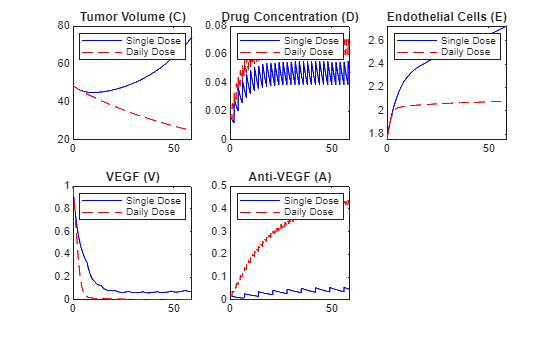

x0_everyday_injection = [T0; C0; E0; V0; A0];

% Computing the ODEs for the 1st day

[T_optimal, Y_optimal] = ode15s(@(t, y) Model_extended(t, y, params_extended), [0:dt:1], x0_everyday_injection); %[0:dt:1] means simulating day 1, with numbers every 0.1 day (or differently defined dt)

% Computing the ODEs for the subsequent days

for i = 1:1:tf-1
    C_end = Y_optimal(end,1);
    D_end = Y_optimal(end,2) + (mod(i,optimal_plan.chemo_interval)==0) * optimal_plan.chemo_dose;
    E_end = Y_optimal(end,3);
    V_end = Y_optimal(end,4);
    A_end = Y_optimal(end,5) + (mod(i,optimal_plan.antivegf_interval)==0) * optimal_plan.antivegf_dose;
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T_optimal(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T_optimal = [T_optimal; Tstep(2:end)];
    Y_optimal = [Y_optimal; Ystep(2:end, :)];
end

%% Plotting the baseline with the optimal 

figure;

subplot(2,3,1);
plot(T3, Y3(:,1), 'b-', T_optimal, Y_optimal(:,1), 'r--');
title('Tumor Volume (C)');
legend('Baseline Dose', 'Optimal Dose');

subplot(2,3,2);
plot(T3, Y3(:,2), 'b-', T_optimal, Y_optimal(:,2), 'r--');
title('Drug Concentration (D)');
legend('Baseline Dose', 'Optimal Dose');

subplot(2,3,3);
plot(T3, Y3(:,3), 'b-', T_optimal, Y_optimal(:,3), 'r--');
title('Endothelial Cells (E)');
legend('Baseline Dose', 'Optimal Dose');

subplot(2,3,4);
plot(T3, Y3(:,4), 'b-', T_optimal, Y_optimal(:,4), 'r--');
title('VEGF (V)');
legend('Baseline Dose', 'Optimal Dose');

subplot(2,3,5);
plot(T3, Y3(:,5), 'b-', T_optimal, Y_optimal(:,5), 'r--');
title('Anti-VEGF (A)');
legend('Baseline Dose', 'Optimal Dose');

Defining the basic function for ODEs solving

function dYdt = Model_extended(t, Y, params)

% Model_extended_modifiable_params - prepares the ODEs for computing the
% variables in time
% 
% Inputs:
%   t          - time vector (not used, but kept for compatibility)
%   Y          - variable values
%   params     - struct of model parameters (params_extended)
%
% Output:
%   dYdt - vector with the ODEs for computation

%Unpacking variables

C = Y(1);  % Tumor
D = Y(2);  % Drug
E = Y(3);  % Endothelial cells
V = Y(4);  % VEGF
A = Y(5);  % Anti-VEGF

%Unpacking the struct
d_c = params.d_c;
b = params.b;
lambda_ce = params.lambda_ce;
d_d = params.d_d;
b_k = params.b_k;
c_M = params.c_M;

E_thres = params.E_thres;
lambda_e = params.lambda_e;
d_e = params.d_e;
E_M = params.E_M;

d_v = params.d_v;
lambda_v0 = params.lambda_v0;
d_b = params.d_b;
k = params.k;
mu_B = params.mu_B;
mu_Bk = params.mu_Bk;


%% ODE Equations 

dCdt = lambda_ce * C * (1 - C / c_M) * (E / E_M) - d_c * C - b * C * D * (E / E_M); % Using logistic model for the tumour growth, adding dependency on E. Hypoxia included via E
dDdt = -d_d * D - b_k * C * D * (E / E_M); % (E / E_M) Adds dependency on the number of the endothelial cells and vascularisation.
dEdt = lambda_e * k * V * (1 - E / E_M); % Logistic model for the endothelial cells growth
dVdt = lambda_v0 * C * (E_thres / (E + E_thres)) - d_v * V - mu_B * A * V; % Added hypoxia as a parameter
dAdt = -d_b * A - mu_Bk * A * V;


% Return
dYdt = [dCdt; dDdt; dEdt; dVdt; dAdt];

end


Defining the function for ODEs solving, with the opportunity to modify parameters based on patient's specifics

function dYdt = Model_extended_modifiable_params(t, Y, params, modifications)

% Model_extended_modifiable_params - prepares the ODEs for computing the
% variables in time with changing parameters based on patient characteristics
% 
% Inputs:
%   t              - time vector (not used, but kept for compatibility)
%   Y              - variable values
%   params         - struct of model parameters (params_extended)
%   modifications  - patients' relative parameters changes
%   %
% Output:
%   dYdt - vector with the ODEs for computation


%Unpacking variables

C = Y(1);  % Tumor
D = Y(2);  % Drug
E = Y(3);  % Endothelial cells
V = Y(4);  % VEGF
A = Y(5);  % Anti-VEGF

% Order of rows of the array with patients' modifications:
% 1. Proliferation rate of the tumor cells
% 2. Carrying capacity tumor cells
% 3. Baseline VEGF secretion by tumor cells
% 4. Clearance of drugs by the kidneys


%Unpacking the struct

d_c = params.d_c;
b = params.b;
lambda_ce = params.lambda_ce * modifications(1);
d_d = params.d_d * modifications(4);
b_k = params.b_k;
c_M = params.c_M * modifications(2);

E_thres = params.E_thres;
lambda_e = params.lambda_e;
d_e = params.d_e;
E_M = params.E_M;

d_v = params.d_v;
lambda_v0 = params.lambda_v0 * modifications(3);
d_b = params.d_b * modifications(4);
k = params.k;
mu_B = params.mu_B;
mu_Bk = params.mu_Bk;


%%Equations (not sure about them). No hypoxia is (yet) used.

dCdt = lambda_ce * C * (1 - C / c_M) * (E / E_M) - d_c * C - b * C * D * (E / E_M); % Using logistic model for the tumour growth, adding dependency on E. Hypoxia included via E
dDdt = -d_d * D - b_k * C * D * (E / E_M); % (E / E_M) Adds dependency on the number of the endothelial cells and vascularisation.
dEdt = lambda_e * k * V * (1 - E / E_M); % Logistic model for the endothelial cells growth
dVdt = lambda_v0 * C * (E_thres / (E + E_thres)) - d_v * V - mu_B * A * V; % Added hypoxia as a parameter
dAdt = -d_b * A - mu_Bk * A * V;


% Return
dYdt = [dCdt; dDdt; dEdt; dVdt; dAdt];

end


Function for sensitivity analysis

function sensitivities = Sensitivity_analysis(Y, params, x0, tspan, a, dose_chemo, dose_antiVEGF, tf, dt)
% Sensitivity_analysis - performs parameter sensitivity analysis
% Inputs:
%   Y               - baseline solution matrix from the initial run (used for baseline)
%   params          - struct of model parameters (params_extended)
%   x0              - initial condition vector [C; D; E; V; A]
%   tspan           - simulation time vector (e.g. 0:0.1:20)
%   a               - relative perturbation (e.g., 0.1 for ±10%)
%   dose_chemo      - chemotherapeutic dose (1) and timing (2) in every step (timing default 2 days)
%   dose_antiVEGF   - antiVEGF drug dose (1) and timing (2) in every step (timing default 7 days)
%   tf              - the number of stimulated days
%   df              - the days between every step of stimulation

%
% Output:
%   sensitivities - matrix [n_params x 2], with sensitivities for ↑ and ↓

   % Sets default values if they are not defined as an argument

    if nargin < 8
        dt = 0.1;  % Default time step
    end
    if nargin < 7
        dose_antiVEGF = [0, 7];  % Default: no anti-VEGF
    end
    if nargin < 6
        dose_chemo = [0, 2];  % Default: no chemotherapy
    end
    if nargin < 5
        a = 0.1;  % Default sensitivity step
    end


    param_names = fieldnames(params);
    num_params = length(param_names);
    sensitivities = zeros(num_params, 2);  % column 1 = up, column 2 = down

    % Use final tumor size from baseline solution as reference
    C_baseline = Y(end, 1);

    for i = 1:num_params
        param = param_names{i};

        % ---- Increase parameter ----
        params_up = params;
        params_up.(param) = params.(param) * (1 + a);
        results_up = run_dosing_simulation(x0, params_up, dose_chemo, dose_antiVEGF, dt, tf);
        C_up = results_up(1) % Extract only the tumour volume
        sensitivities(i,1) = abs((C_up - C_baseline) / C_baseline) / a;

        % ---- Decrease parameter ----
        params_down = params;
        params_down.(param) = params.(param) * (1 - a);
        results_down = run_dosing_simulation(x0, params_down, dose_chemo, dose_antiVEGF, dt, tf);
        C_down = results_down(1) % Extract only the tumour volume
        sensitivities(i,2) = abs((C_down - C_baseline) / C_baseline) / a;
    end
    % Plot results
    figure;
    bar(categorical(param_names), sensitivities);
    legend('↑ Increased', '↓ Decreased');
    ylabel('Normalized Sensitivity');
    title('Sensitivity of Final Tumor Size (C) to Parameters');
end

function results_final = run_dosing_simulation(x0, params, dose_chemo, dose_antiVEGF, dt, tf)
% Simulates tumor model over tf days with dosing

    % First day simulation
    tspan = 0:dt:1;
    [T, Y] = ode15s(@(t, y) Model_extended(t, y, params), tspan, x0);

    for i = 1:tf-1
        C_end = Y(end,1);
        D_end = Y(end,2) + (mod(i,dose_chemo(2))==0) * dose_chemo(1);
        E_end = Y(end,3);
        V_end = Y(end,4);
        A_end = Y(end,5) + (mod(i,dose_antiVEGF(2))==0) * dose_antiVEGF(1);

        x0 = [C_end; D_end; E_end; V_end; A_end];
        t0 = T(end);
        t1 = t0 + 1;
        tstep = t0:dt:t1;

        [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params), tstep, x0);

        T = [T; Tstep(2:end)];
        Y = [Y; Ystep(2:end, :)];
    end

    results_final = Y(end, :);  % Final variables size, indexed 1-5 as defined in the model
end

Function on optimised dosing schedules (Work in progress, not proud of using AI to generate me the code for the cumulative dose cost, but it is late)

function optimal_plan = optimise_dosing_schedule(x0, params, dt, tf)
    chemo_doses = 0.002:0.01:0.05;  % Defines in what volume is the chemotherapeutic administered (baseline 0.171)
    antivegf_doses = 0.003:0.01:0.07; % Defines in what volume is anti-VEGF drug administered (baseline 0.02)
    chemo_days = [0, 7:-1:1]; % Defines how often the chemotherapeutic is administered (baseline 2)
    antivegf_days = [0, 14:-1:1]; % Defines how often the anti-VEGF drug is administered (baseline 7)
    max_chemo_concentration = 0.4;     % Maximal total acceptable chemo volume in the organism
    max_anti_VEGF_concentration = 0.5;      % Maximal total acceptable anti-VEGF volume in the organism
    w1 = 0.7;  % Weight of the tumour control
    w2 = 0.3;  % Weightof the drugs dosing
    T0 = x0(1);  % Initial tumour volume

    % Normalisation references for cumulative dose cost
    max_chemo_permit = max(chemo_doses) * ceil(tf / min(chemo_days(chemo_days > 0))); %Calculating the theoretical maximal chemotherapeutic dose during the simulation days
    max_anti_permit  = max(antivegf_doses) * ceil(tf / min(antivegf_days(antivegf_days > 0)));  %Calculating the theoretical maximal anti-VEGF drug dose during the simulation days


    best_cost = inf;
    optimal_plan = struct('chemo_dose', 0, 'chemo_interval', 0, ...
                          'antivegf_dose', 0, 'antivegf_interval', 0, ...
                          'cost', inf);
    
    for i = 1:length(chemo_doses)
        for j = 1:length(antivegf_doses)
            for k = 1:length(chemo_days)
                for l = 1:length(antivegf_days)

                    dose_chemo = [chemo_doses(i), chemo_days(k)];
                    dose_anti  = [antivegf_doses(j), antivegf_days(l)];

                    results = run_dosing_simulation(x0, params, dose_chemo, dose_anti, dt, tf);
                    final_tumor = results(1);       % C
                    final_chemo = results(2);       % D
                    final_anti_VEGF  = results(5);  % A

                    % Toxic plan? Skip it
                    if final_chemo > max_chemo_concentration || final_anti_VEGF > max_anti_VEGF_concentration
                        continue;
                    end

                    % Safe → Evaluate cost
                    Nchemo = max(1, ceil(tf / max(1, dose_chemo(2)))); % Calculating the number of chemotherapeutic doses given during simulation
                    Nanti  = max(1, ceil(tf / max(1, dose_anti(2)))); % Calculating the number of anti-VEGF drug doses given during simulation
                    

                    cum_chemo = dose_chemo(1) * Nchemo; % Calculating the total volume of the chemotherapeutic given during the stimulation
                    cum_anti  = dose_anti(1) * Nanti; % Calculating the total volume of the anti-VEGF drug given during the stimulation

                    drug_score = 0.5 * (cum_chemo / max_chemo_permit + cum_anti / max_anti_permit);  % Calculating the drug score
                    tumour_score = final_tumor / T0; % Calculating the tumour score based on the final cell concentration

                    cost = w1 * tumour_score + w2 * drug_score; % Calculating the final cost based on the weights

                    % Compare the current dosage cost with the best one 

                    if cost < best_cost
                        best_cost = cost;
                        optimal_plan.chemo_dose = dose_chemo(1);
                        optimal_plan.chemo_interval = dose_chemo(2);
                        optimal_plan.antivegf_dose = dose_anti(1);
                        optimal_plan.antivegf_interval = dose_anti(2);
                        optimal_plan.final_tumor = final_tumor;
                        optimal_plan.total_chemo = cum_chemo;
                        optimal_plan.total_antivegf = cum_anti;
                        optimal_plan.cost = cost;
                    end
                end
            end
        end
    end

    % Report result
    fprintf('\nOptimal Plan (Safe Only):\n');
    fprintf('  Chemo: %.3f every %d days (total %.3f)\n', ...
        optimal_plan.chemo_dose, optimal_plan.chemo_interval, optimal_plan.total_chemo);
    fprintf('  Anti-VEGF: %.3f every %d days (total %.3f)\n', ...
        optimal_plan.antivegf_dose, optimal_plan.antivegf_interval, optimal_plan.total_antivegf);
    fprintf('  Final Tumor Volume: %.2f mm³\n', optimal_plan.final_tumor);
    fprintf('  Weighted Cost: %.3f\n', optimal_plan.cost);
end

